# Analysing visual coding electrophysiology data from the Allen Brain Observatory, with the Brain Observatory Toolbox

The Allen Brain Observatory resource [1] comprises datasets of neural activity obtained from the mouse visual cortex collected during visual stimulus presentation. The Neuropixels dataset [[2](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels)] consists of neural activity recordings obtained using multi-channel electrophysiology.

This example demonstrates how to access, search, and filter data from the Visual Coding - 2P dataset using the [Brain Observatory Toolbox](https://github.com/emeyers/Brain-Observatory-Toolbox) (BOT). It also shows how to perform some simple analyses of visual responses by neurons in mouse primary visual cortex. Neural response properties such as orientation tuning are quantified, along with basic behavioural analysis.

## About the Brain Observatory Toolbox (BOT)

The BOT is a MATLAB toolbox for accessing, manipulating and analysing neurophysiology data from the Allen Brain Observatory. The BOT provides convenient methods for identifying data sets of interest, and manages downloading and caching of data from the Allen Brain Observatory.

## Obtaining and examining manifests of experimental data

The Neuropixels database is summarised in a number of manifest tables, listing experimental `sessions;` and recordings broken down by `probes`, `channels` and `units`.

These tables are accessed using several `fetch...()` factory functions, and presented as MATLAB `table` objects.

% - Obtain sessions, probes, channels and units tables
sessions = bot.fetchSessions('ephys');
probes = bot.fetchProbes();
channels = bot.fetchChannels();
units = bot.fetchUnits(); %#ok<NASGU> 

You can use these tables to locate sessions or individual recordings that meet your criteria.

% - Display the sessions manifest
head(sessions)

ans = 8×18 table
    type     date_of_acquisition     fail_eye_tracking       id        isi_experiment_id    published_at    specimen_id        session_type           specimen      well_known_files    age_in_days    sex                      full_genotype                      has_nwb    unit_count    channel_count    probe_count    ephys_structure_acronyms
    _____    ____________________    _________________    _________    _________________    ____________    ___________    _____________________    ____________    ___________

% - Select sessions that include valid eye tracking data
sessions = sessions(~sessions.fail_eye_tracking, :);

% - Select sessions on wild-type animals
sessions = sessions(sessions.full_genotype == "wt/wt", :)

sessions = 26×18 table
    type     date_of_acquisition     fail_eye_tracking       id        isi_experiment_id    published_at    specimen_id         session_type            specimen      well_known_files    age_in_days    sex    full_genotype    has_nwb    unit_count    channel_count    probe_count    ephys_structure_acronyms
    _____    ____________________    _________________    _________    _________________    ____________    ___________    _______________________    ____________    ________________    

## Obtaining and examining a single experimental session

Let's choose the first of the remaining experimental sessions in the `sessions` table, and examine it in more detail. In the BOT, experimental data are represented as lightweight objects, with lazy loading of large data files only when necessary.

A single experimental session is obtained using the `bot.session()` factory function:

% - Obtain a single experimental session
sess = bot.session(sessions(1, :))

sess =   ephyssession with properties:

   Metadata
                          metadata: [1×1 struct]
                                id: 742951821
                       age_in_days: 120
                               sex: M
                     full_genotype: "wt/wt"
                      session_type: brain_observatory_1.1
                         num_units: 893
                        num_probes: 6
                      num_channels: 2219

   Contained experimental data
                            probes: [6×26 table]
                          channels: [2219×33 table]
                             units: [893×59 table]

   Lazy loading
                 rig_geometry_data: '[cached]'
                rig_equipment_name: '[cached]'
      inter_presentation_intervals: '[cached]'
                     running_speed: '[cached]'
                    mean_waveforms: '[cached]'
            stimulus_presentations: 

The `session` object collects a number of useful metadata properties (including detailed metadata in `.metadata`); a set of tables indicating the experimental data contained by this session; and a number of lazy loading properties, which indicate available data and whether or not that data is already downloaded into the BOT cache.

For the lazy loading properties, `'[cached]'` indicates that the NWB data file has previously been downloaded from the Allen Brain Observatory; `'[not cached]'` indicates that data is not yet downloaded. Accessing one of these property will cause data to be loaded from the cache, or downloaded if necessary. Many of these data files can be several GB in size.

Let's look at the metadata for this session:

sess.metadata

ans = struct with fields:
                        type: EPhys
         date_of_acquisition: 26-Oct-2018 19:47:04
           fail_eye_tracking: 0
                          id: 742951821
           isi_experiment_id: 732238627
                published_at: 03-Oct-2019
                 specimen_id: 723627604
                session_type: brain_observatory_1.1
                    specimen: [1×1 struct]
            well_known_files: [1×1 struct]
                 age_in_days: 120
                         sex: M
               full_genotype: "wt/wt"
                     has_nwb: 1
                  unit_count: 893
               channel_count: 2219
                 probe_count: 6
    ephys_structure_acronyms: {8×1 cell}


We can see that this was indeed a male (`sex = M`) "wild-type" animal (`full_genotype = "wt/wt"`); the session contains data from 6 probes, comprising 2219 channels, and 893 individual units (putative neurons) were identified.

We can examine the session to see which units in this session were recorded from which brain structures:

sess.structurewise_unit_counts

ans = 7×2 table
    ephys_structure_acronym    count
    _______________________    _____

             grey               554 
             VIS                108 
             VISrl               79 
             VISl                52 
             VISal               44 
             VISp                33 
             VISpm               23 


## Examining the stimuli used in this experiment

The properties `.stimulus_names`, `.stimulus_conditions`, `.stimulus_presentations` etc. contain information about what stimuli were presented in this session, and details about the stimulus parameters and in what order the stimuli were presented.

% Show which stimuli were presented in this session
sess.stimulus_names

ans = 8×1 string array
    "drifting_gratings"
    "flashes"
    "gabors"
    "natural_movie_one"
    "natural_movie_three"
    "natural_scenes"
    "spontaneous"
    "static_gratings"


% Get a table with detailed parameters for each stimulus
head(sess.stimulus_conditions)

ans = 8×17 table
    contrast      mask       opacity    orientation                 phase                       size         spatial_frequency    stimulus_name    temporal_frequency      units      stimulus_block_condition_id    frame    x_position    y_position      color_triplet      color    stimulus_condition_id
    ________    _________    _______    ___________    ________________________________    ______________    _________________    _____________    __________________    _________    ___________________________

% Get a full table of inidividual stimulus presentations
head(sess.stimulus_presentations)

ans = 8×19 table
    contrast    stimulus_block_id    orientation                 phase                       size         spatial_frequency    start_time    stimulus_block    stimulus_name    stop_time    temporal_frequency    stimulus_block_condition_id    frame    x_position    y_position    stimulus_presentation_id    color    duration    stimulus_condition_id
    ________    _________________    ___________    ________________________________    ______________    _________________    __________    ______________    _______

## Visualise pupil location

The pupil tracking data is available for some sessions, via the method `.fetch_pupil_data()`. Here we'll visualise the pupil location as a location density map.

% Get the table of pupil locations
pupil_loc = sess.fetch_pupil_data()

pupil_loc = 288131×16 table
    timestamps    corneal_reflection_center_x    corneal_reflection_center_y    corneal_reflection_height    corneal_reflection_width    corneal_reflection_phi    pupil_center_x    pupil_center_y    pupil_height    pupil_width    pupil_phi    eye_center_x    eye_center_y    eye_height    eye_width    eye_phi 
    __________    ___________________________    ___________________________    _________________________    ________________________    ______________________    ______________    ______________    ____________    ___________</

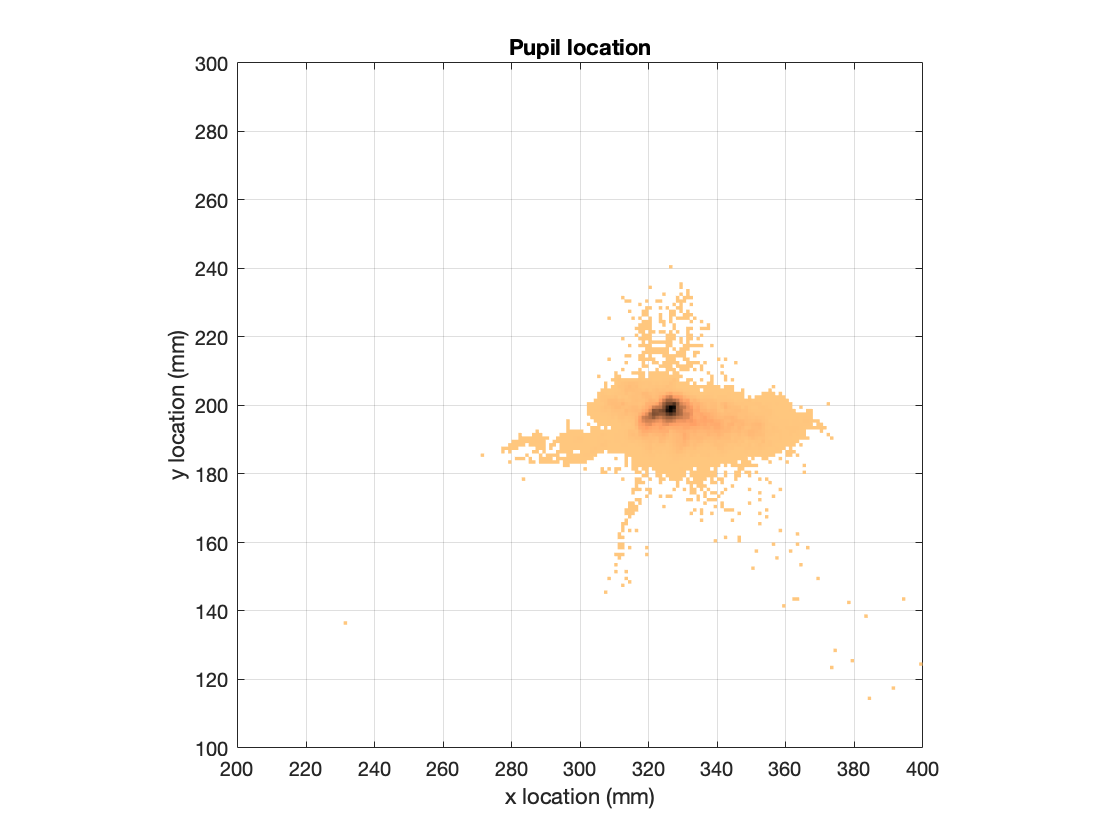

% Plot a 2D histogram of pupil location
histogram2(pupil_loc.pupil_center_x, pupil_loc.pupil_center_y, 'DisplayStyle', 'tile');
xlim([200 400]);
ylim([100 300]);
cmap = copper();
colormap(cmap(end:-1:1, :));
axis square;
xlabel('x location (mm)');
ylabel('y location (mm)');
title('Pupil location');

## Examining data from a single unit

Let's access the first recoded unit in this session from primary visual cortex (`'VISp'`). To do so, we first locate a `units` table row, or `unit_id` of interest, and then use the `bot.units()` factory function to get a `unit` object;

units = sess.units;
units = units(units.ephys_structure_acronym == 'VISp', :)

units = 33×59 table
    waveform_PT_ratio    waveform_amplitude    amplitude_cutoff    cumulative_drift     d_prime      waveform_duration    ephys_channel_id    epoch_name_quality_metrics    epoch_name_waveform_metrics    firing_rate    waveform_halfwidth       id        isi_violations    isolation_distance       L_ratio         max_drift     nn_hit_rate     nn_miss_rate     presence_ratio    quality     waveform_recovery_slope    waveform_repolarization_slope    silhouette_score     snr      waveform_spread    waveform_velocity_above    wavef

% Obtain a `unit` object for the first unit
unit = bot.unit(units(1, :)) %#ok<NASGU> 

unit =   ephysunit with properties:

     session: [1×1 bot.internal.ephyssession]
     channel: [1×1 bot.internal.ephyschannel]
       probe: [1×1 bot.internal.ephysprobe]
    metadata: [1×1 struct]
          id: 950946855


% or alternatively:
unit = bot.unit(units{1, 'id'})

unit =   ephysunit with properties:

     session: [1×1 bot.internal.ephyssession]
     channel: [1×1 bot.internal.ephyschannel]
       probe: [1×1 bot.internal.ephysprobe]
    metadata: [1×1 struct]
          id: 950946855


The `unit` object holds references to the `session`, `probe` and `channel` that it belongs to, as well as `metadata` about this unit:

unit.metadata

ans = struct with fields:
                    waveform_PT_ratio: 0.3453
                   waveform_amplitude: 137.9305
                     amplitude_cutoff: 0.0061
                     cumulative_drift: 87.6300
                              d_prime: 6.9465
                    waveform_duration: 0.8104
                     ephys_channel_id: 850184574
           epoch_name_quality_metrics: 'complete_session'
          epoch_name_waveform_metrics: 'complete_session'
                          firing_rate: 0.4492
                   waveform_halfwidth: 0.1511
                                   id: 950946855
                       isi_violations: 0
                   isolation_distance: 75.0034
                              L_ratio: 7.6792e-05
                            max_drift: 41.2100
                          nn_hit_rate: 0.9744
                         nn_miss_rate: 2.6876e-04
                       presence_ratio: 0.9600
                              quality: 'good'
              wa

## References

[1] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 

[2] Copyright 2016 Allen Institute for Brain Science. Visual Coding – Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).